%%c l e a r up
clear all ; close all ;

P0_true = -10;
gamma_true = 2.5;

## Data Generation 

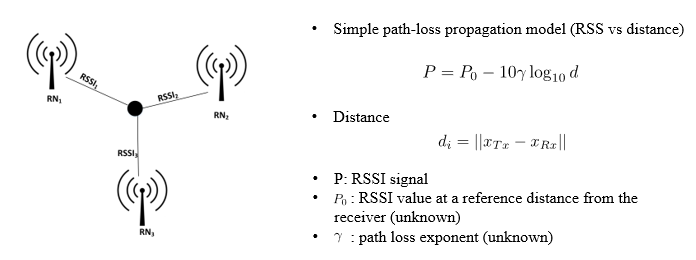

anchor_matrix =[0 0; 10 0; 0 10; 10 10 ]

anchor_matrix =      0     0
    10     0
     0    10
    10    10


anchor_matrix =      0     0
    10     0
     0    10
    10    10
    20     5
    30    10


m=length(anchor_matrix);
r= [5 5]

r =      5     5


distance = sqrt((r(1)-anchor_matrix(:,1)).^2+(r(2)-anchor_matrix(:,2)).^2);

distance =     7.0711
    7.0711
    7.0711
    7.0711
   15.0000
   25.4951


noise=3;
P=RSSI_virtual(P0_true,gamma_true,distance,noise);

P =   -64.4330
  -58.0351
  -61.7530
  -61.6325
  -78.1871
  -92.4289


**Parameter Estimation for P0 and gamma **

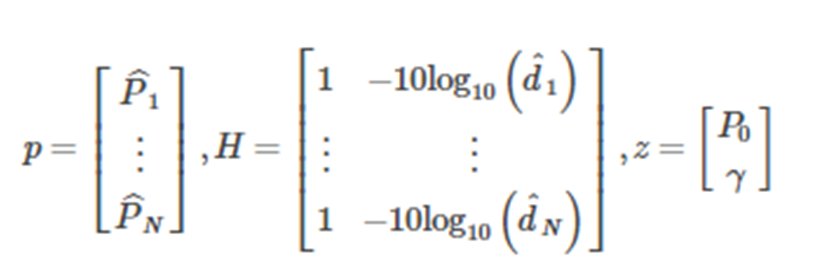

H= [ones(m,1) -10*log(distance)];

theta_hat = (H'*H)\H'*P

theta_hat =   -14.8904
    2.3756


**User Define Function (RSSI calculation)**

function power = RSSI_virtual(P0,gamma,distance,noise)
n=length(distance);
power = P0-10*gamma*log(distance) +noise*randn(n,1);
end